# Affine Frame

The other modlues in this series are

[**Introduction**](matlab:open('./Introduction.mlx'))**: **An interactive lesson on the definition of parametric equations, frames, and group transformations, all from the point of view of curves and trajectories as vector-valued parametric functions.

[**Fernet Serret frame**](matlab:open('./Frenet_Serret_Frames.mlx'))**: **An interactive lesson on the Frenet Serret frame, which is the most commonly used and known moving frame method. Applications include generating trajectories using parameters like curvature and torsion in mechanical systems such as multi-link manipulators and unicycle models.

[**Affine frame**](matlab:open('./Affine_Frame.mlx'))**: **An interactive lesson on the equi-affine frame for 2-D as well as 3-D curves, defining concepts such as affine arc-length and affine curvature.

**Before you get started:**

- This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon  at the top right of the Live Editor pane.  

- The plots at each section of this Live Script are built upon variables that might be created in the previous sections. To get the intended visuals and results, run the sections consecutively.    

 
clc; clear;

## Defining the Equi-affine Frame

Consider a curve $\mathbf{r}(t)$. For the Euclidean frames (Frenet-Serret frame and natural Frenet frame), the curve is reparametrized to the parameter $s(t)$ such that $\left|\left| \frac{d\mathbf{r}}{ds}\right| \right|\equiv 1$, i.e. unit speed. The resulting Eucliean frames were invariant under Euclidean transformations, such as rotations or translations. For example, for the Frenet-Serret frame the classical curvature $\kappa$ and torsion $\tau$ are both preserved under such transformations. However, Euclidean frames and invariants are not preserved under equi-affine transformations. Consider the following ellipse in $\mathbb{R}^2$:

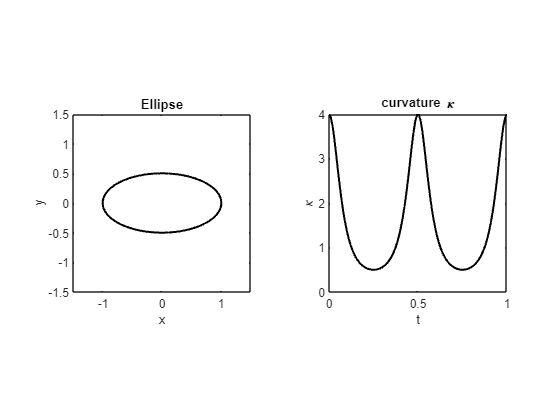

 
drawEllipse(1, 0);

If we rotate the ellipse by a factor of $\theta$(a Euclidean transformation), we see that the classical curvature $\kappa$ remains invariant:

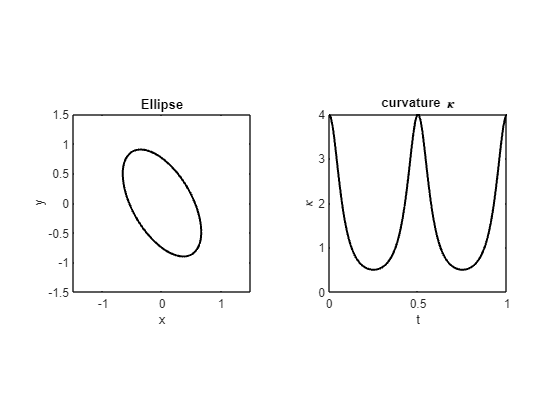

theta = 120;  
drawEllipse(1, deg2rad(theta));

However if we apply an equi-affine transformation (stretching/shrinking by a factor of $\alpha$), we see that the classical curvature is not preserved:

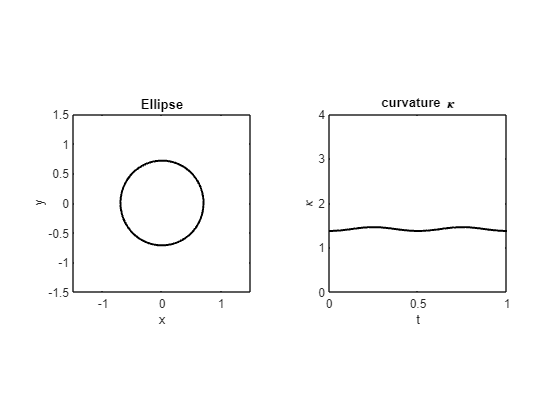

alpha = 0.7;  
drawEllipse(alpha, 0)

Thus we would like to find a set of frames $\{\mathbf{a}_1, \mathbf{a}_2, \mathbf{a}_3\}$ and corresponding invariants that are preserved under such equi-affine transformations. Since equi-affine transformations are area-preserving, the condition that


$$\det(\mathbf{a}_1 \  \mathbf{a}_2\ \mathbf{a}_3) \equiv 1$$


i.e. the volume of the parallelepiped created by the frames is constant, arises naturally as the *nondegeneracy* condition. 

If we define the frame, similar to the Euclidean case, to be the derivatives of the curve, i.e.


$$\mathbf{a}_1(t) = \alpha \dot{\mathbf{r}}$$



$$\mathbf{a}_2(t) = \alpha \ddot{\mathbf{r}}$$



$$\mathbf{a}_3(t) = \alpha \dddot{\mathbf{r}}$$


Then we see that for the area preserving condition to hold, 


$$\alpha = \frac{1}{\det(\dot{\mathbf{r}} \ \ddot{\mathbf{r}} \ \dddot{\mathbf{r}})^{1/3}}$$


We would like to find an equi-affine arclength parameter $\sigma(t)$ such that for the re-parametrized curve $r(\sigma)$, the equi-affine frame is simply


$$\mathbf{a}_1(\sigma) = \mathbf{r}'$$



$$\mathbf{a}_2(\sigma) = \mathbf{r}''$$



$$\mathbf{a}_3(\sigma) = \mathbf{r}'''$$


Where $\mathbf{r}' = \frac{d\mathbf{r}}{d\sigma}$ . However, since the nondegeneracy condition depends on dimensionality of the space, $\sigma$ will have different definitions for curves in $\mathbb{R}^2$ and $\mathbb{R}^3$. 

 *Note*: The $\mathbf{a}_i$'s are in general not orthonormal, and unlike the Euclidean case, where the arc-length parameter only depends on the first derivative, or tangrent, of the curve, we see that the equi-affine arclength is defined by the first, second, and third derivatives. 

## Affine frame in 2-D Space

In $\mathbb{R}^2$, the nondegeneracy condition for the equi-affine frame is 


$$\det(\mathbf{a}_1 \ \mathbf{a}_2) = \det(\mathbf{r}' \  \mathbf{r}'')=1$$


Using the chain rule, we know that 


$$\frac{d\mathbf{r}}{d\sigma} = t'(\sigma)\frac{d\mathbf{r}}{dt}$$



$$\frac{d^2\mathbf{r}}{d\sigma^2} = t'(\sigma)^2\frac{d^2\mathbf{r}}{dt^2} + R\left(\frac{d\mathbf{r}}{d\sigma}\right)$$


where $R\left(\frac{d\mathbf{r}}{d\sigma}\right)$ is a term that does not affect the determinant above (since $\det(\mathbf{r}' \ R(\mathbf{r}'))=0$). Thus 


$$\det(\mathbf{r}'(\sigma) \  \mathbf{r}''(\sigma)) = t'(\sigma)^3 \det(\dot{\mathbf{r}}(t) \  \ddot{\mathbf{r}}(t))$$


which suggests that for the determinant to be $1$, the equi-affine arc-length parameter will have the following definition:


$$\sigma(t) = \int_{0}^{t}\ \sqrt[3]{\det(\dot{\mathbf{r}}(u) \ \ddot{\mathbf{r}}(u))} du$$


equivalently we can define the *equi-affine speed* to be


$$\dot{\sigma}(t) =  \sqrt[3]{\det(\dot{\mathbf{r}} \ \ddot{\mathbf{r}})}$$


Using the fact that $\frac{d\det(\mathbf{r}' \  \mathbf{r}'')}{d\sigma} = 0$, we find that $\mathbf{r}''' $ is linearly dependent on $\mathbf{r}'$, i.e. they are proportional to each other. Since $\mathbf{r}''' = \mathbf{a}_2'$ and $\mathbf{r}' = \mathbf{a_1}$, we arrive at the full dynamics of the equi-affine frame in $\mathbb{R}^2$ 


$$\mathbf{r}' = \mathbf{a}_1$$



$$\mathbf{a}_1' = \mathbf{a}_2$$



$$\mathbf{a}_2' = -k(\sigma)\mathbf{a}_1$$


We call the term $k$ the *equi-affine curvature* of the curve, and similar to the invariants in previous frames, they define the curve uniquely up to equi-affine transformations. 

Equivalently, we can write the dynamics of frames as a matrix differential equation:


$$\pmatrix{\mathbf{a}_1 & \mathbf{a}_2}' = \pmatrix{\mathbf{a}_1 & \mathbf{a}_2} \pmatrix{0  & -k(\sigma) \cr 1  & 0}$$


Compare this to the Euclidean frame, which is defined by two unit vectors: the tangent $\mathbf{T}$ and a normal $\mathbf{N}$ that is orthogonal to $\mathbf{T}$. 

In the affine frame case, the two vectors defining the frame $\{\mathbf{a}_1, \mathbf{a}_2\}$ only have to satisfy the area-preserving condition. 

For example, take a look at the equi-affine frame for the following parabola:

 
% generate curve
syms t
tspan = linspace(-1, 1, 100);
r(t) = [t; t^2];
r_dot = diff(r);
r_ddot = diff(r_dot);
r_dddot = diff(r_ddot);
sigma_dot = det([r_dot r_ddot])^(1/3);
e1 = r_dot/sigma_dot;
e2 = diff(e1)/sigma_dot;
numr = double(cell2sym(r(tspan)));
numx = numr(1, :);
numy = numr(2, :);
nume1 = double(cell2sym(e1(tspan)));
nume2 = double(cell2sym(e2(tspan)));

% plot
figure
hold on;

plot(numx, numy, 'Color', 'k', 'LineWidth', 2)
axis equal
ax = gca;
quiverSize = max([range(ax.XLim) range(ax.YLim)])/5;
[XLim, YLim, ~] = padax(ax, quiverSize, 0);
ax.XLim = XLim;
ax.YLim = YLim;
xlabel('x')
ylabel('y')

qT = quiver(numx(1), numy(1), nume1(1,1), nume1(2, 1), quiverSize ,'r', 'LineWidth',1.5);
qN = quiver(numx(1), numy(1), nume2(1, 1), nume2(2, 1), quiverSize ,'b', 'LineWidth',1.5);
qU = quiver(numx(1), numy(1), 0, 0, 'o', 'LineWidth',1.5, 'MarkerEdgeColor', 'k', 'MarkerFaceColor', 'w');
para = parallelogram2(numr(:,1), nume1(:,1)*quiverSize, nume2(:,1)*quiverSize);
p1 = plot(para, "FaceColor", '#0072BD');
legend("r","a_1","a_2", "", "Affine Frame Parallelogram", 'Location', 'southwest')
% legend boxoff
title('Parabolic Trajectory')

 *Note:* If the animations are causing slowdowns or not working correctly, uncheck the "animation" box for a simplified view of the figure.

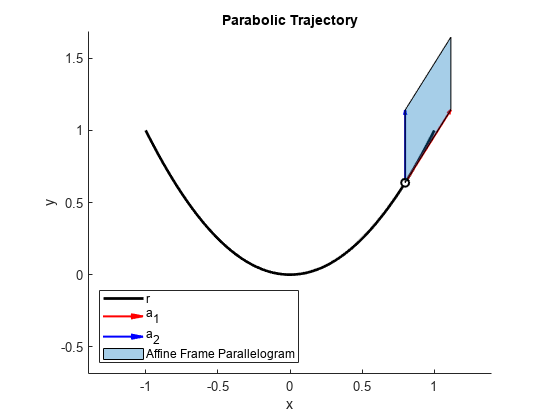

aFlag = true;
%animate
if aFlag
    for i=1:length(tspan)-10
     
      qT.XData = numx(i);
      qT.YData = numy(i);
      qT.UData = nume1(1, i);
      qT.VData = nume1(2, i);
    
      qN.XData = numx(i);
      qN.YData = numy(i);
      qN.UData = nume2(1, i);
      qN.VData = nume2(2, i);
    
      qU.XData = numx(i);
      qU.YData = numy(i);
      qU.UData = 0;
      qU.VData = 0;
    
      p1.Shape = parallelogram2(numr(:,i), nume1(:,i)*quiverSize, nume2(:,i)*quiverSize);
      area(p1.Shape);
      drawnow
    end
end
hold off

Observe that the area of the parallelogram formed by the affine frame is equal to 1, i.e. $\det(\mathbf{e}_2, \mathbf{e}_2) \equiv 1$, for all points of the curve. 

For curves in $\mathbb{R}^2$, there is only one affine curvature $k$. Similar to how constant classical Euclidean curvature is associated with circular trajectories, constant affine curvature implies conic trajectories, i.e. parabolas, ellipses, and hyperbolas. In fact (see p.2) :

- For $k = 0$, the curve is a *parabola*.

- For $k < 0$, the curve is a hyperbola.

- For $k>0$, the curve is an ellipse

See the following examples of the resulting curves for various constant equi-affine curvatures:

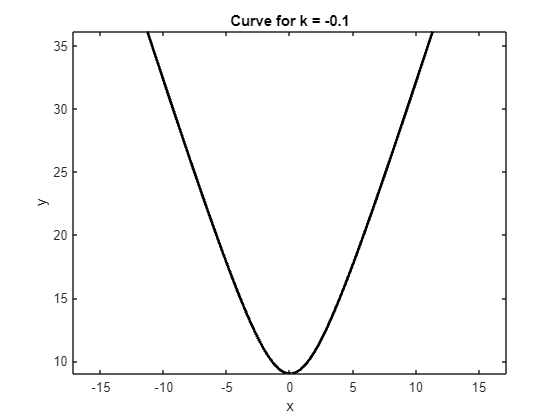

k = -0.1; 
% calculate resulting curve from k
syms t
tspan = linspace(-2*pi, 2*pi, 200);
mu = sqrt(-k);
if k ~= 0
    r(t) = [1/mu*sinh(mu*t); 1/mu^2*cosh(mu*t) - 1];
else
    r(t) = [t; 1/2*t^2];
end
% calculate frames
r_dot = diff(r);
r_ddot = diff(r_dot);
r_dddot = diff(r_ddot);
sigma_dot = det([r_dot r_ddot])^(1/3);
e1 = r_dot/sigma_dot;
e2 = diff(e1)/sigma_dot;

% convert to vectors
numr = double(cell2sym(r(tspan)));
numx = numr(1, :);
numy = numr(2, :);
nume1 = double(cell2sym(e1(tspan)));
nume2 = double(cell2sym(e2(tspan)));

% plot
figure
plot(numx, numy, 'Color', 'k', 'LineWidth', 2);
axis equal
xlabel('x');
ylabel('y');
title(['Curve for k = ' num2str(k)]);

% animate (uncomment to see animation, will take away choice of k)
% for i = -1:.05:1
%     time = i;
%     title(['Curve with Constant Affine Curvature k = ' num2str(time) ')'])
%     tspan = linspace(-2*pi, 2*pi, 100);
%     mu = sqrt(-i);
%     if i ~= 0
%         r(t) = [1/mu*sinh(mu*t); 1/mu^2*cosh(mu*t) - 1];
%     else
%         r(t) = [t; 1/2*t^2];
%     end
%    
%     numr = double(cell2sym(r(tspan)));
%     numx = numr(1, :);
%     numy = numr(2, :);
%     p1.XData = numx;
%     p1.YData = numy;
%     drawnow
% end

## Affine frame in 3-D Space

Using similar calculations as $\mathbb{R}^2$, we find that the equi-affine arclength for a curve in $\mathbb{R}^3$ is defined by


$$\sigma(t) = \int_{0}^{t}\ \sqrt[6]{\det(\dot{\mathbf{r}}(u) \ \ddot{\mathbf{r}}(u) \ \dddot{\mathbf{r}}(u))} du$$


which gives the system of dynamical equations


$$\mathbf{r}' = \mathbf{a}_1$$



$$\mathbf{a}_1' = \mathbf{a}_2$$



$$\mathbf{a}_2' = \mathbf{a}_3$$



$$\mathbf{a}'_3 = -k_1 \mathbf{a}_1-k_2\mathbf{a}_2$$


or equivalently


$$\pmatrix{\mathbf{a}_1 & \mathbf{a}_2 &\mathbf{a}_3}' = \pmatrix{\mathbf{a}_1 & \mathbf{a}_2 & \mathbf{a}_3} \pmatrix{0  & 0 & -k_1(\sigma) \cr 1  & 0 & -k_2(\sigma) \cr 0 & 1 & 0}$$


In this case $k_1$ and $k_2$ are the two equi-affine curvatures of the curve.

 
clear
syms t
% calculate curve 
x(t) = sqrt(2)/2*cos(t);
y(t) = sqrt(2)/2*sin(t);
z(t) = sqrt(2)/2*t;
r(t) = [x; y; z];
r_dot = diff(r);
r_ddot = diff(r_dot);
r_dddot = diff(r_ddot);
sigma_dot = simplify(det([r_dot r_ddot r_dddot])^(1/6));
r_pr = r_dot/sigma_dot;
r_ppr = diff(r_pr)/sigma_dot;
r_pppr = diff(r_ppr)/sigma_dot;

% convert to vectors
tspan = linspace(0, 2*pi, 200);
numr = double(cell2sym(r(tspan)));
numT = double(cell2sym(r_pr(tspan)));
numN = double(cell2sym(r_ppr(tspan)));
numB = double(cell2sym(r_pppr(tspan)));

% plot
figure
x = numr(1, :);
y = numr(2, :);
z = numr(3, :);
plot3(x, y, z,'k','LineWidth',2)
hold on

axis equal
ax = gca;
quiverSize = max([range(ax.XLim) range(ax.YLim) range(ax.ZLim)])/5;    
qT = quiver3(x(1), y(1), z(1), numT(1, 1), numT(2, 1), numT(3, 1), quiverSize ,'SeriesIndex', 1, 'LineWidth',1.5);
qN = quiver3(x(1), y(1), z(1), numN(1, 1), numN(2, 1), numN(3, 1), quiverSize ,'SeriesIndex', 2, 'LineWidth',1.5);
qB = quiver3(x(1), y(1), z(1), numB(1, 1), numB(2, 1), numB(3, 1), quiverSize ,'SeriesIndex', 3, 'LineWidth',1.5);
qU = quiver3(x(1), y(1), z(1), 0, 0, 0, 'o', 'LineWidth',1.5, 'MarkerEdgeColor', 'k', 'MarkerFaceColor', 'w');
para = parallelogram3(numr(:, 1), numT(:, 1)*quiverSize, numN(:, 1)*quiverSize, numB(:,1)*quiverSize);
p1 = plot(para, 'FaceColor', '#4DBEEE', 'FaceAlpha', .5, 'LineStyle', ':');
[XLim, YLim, ZLim] = padax(ax, quiverSize, 1);
ax.XLim = XLim;
ax.YLim = YLim;
ax.ZLim = ZLim;
grid on
view([-32.5 30])
xlabel('x')
ylabel('y')
zlabel('z')

 *Note:* If the animations are causing slowdowns or not working correctly, uncheck the "animation" box for a simplified view of the figure.

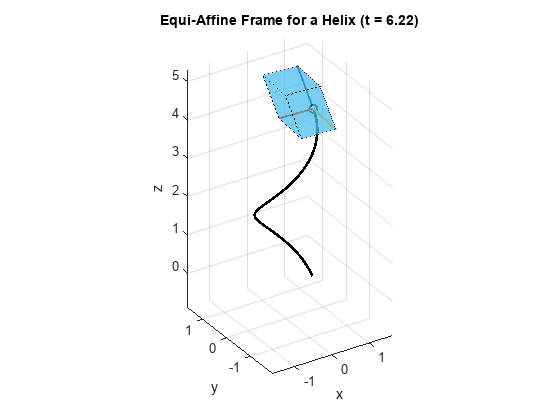

aFlag = true;
% animate
if aFlag
    for i=1:length(x)-2
      title(['Equi-Affine Frame for a Helix (t = ' num2str(tspan(i)) ')'])
      p = numr(:, i);
      v1 = numT(:, i)*quiverSize;
      v2 = numB(:, i)*quiverSize;
      v3 = numN(:, i)*quiverSize;
      ax.View = [-32.5, 30];
    
      qT.XData = x(i);
      qT.YData = y(i);
      qT.ZData = z(i);
      qT.UData = numT(1, i);
      qT.VData = numT(2, i);
      qT.WData = numT(3, i);
    
      qN.XData = x(i);
      qN.YData = y(i);
      qN.ZData = z(i);
      qN.UData = numN(1, i);
      qN.VData = numN(2, i);
      qN.WData = numN(3, i);
    
      qB.XData = x(i);
      qB.YData = y(i);
      qB.ZData = z(i);
      qB.UData = numB(1, i);
      qB.VData = numB(2, i);
      qB.WData = numB(3, i);
    
      qU.XData = x(i);
      qU.YData = y(i);
      qU.ZData = z(i);
      qU.UData = 0;
      qU.VData = 0;
      qU.WData = 0;
      
      p1.Vertices = [p p+v1 p+v2 p+v3 p+v1+v2 p+v2+v3 p+v1+v3 p+v1+v2+v3]';
      p1.Faces = [1 2 5 3; 1 2 7 4; 1 3 6 4; 8 6 3 5; 8 7 2 5; 8 7 4 6];
    
      drawnow 
      
    end
end
hold off

## Problems

- Prove that for the case of $\mathbb{R}^2$, a constant equi-affine curvature $k$ gives the different cases of the conic sections depending on the sign of $k$.

- For the $\mathbb{R}^2$ case, find a relationship between the equi-affine curvature $k$ and the classical Euclidean curvature $\kappa$.

- Show that for a helix, i.e. the curve $\mathbf{r}(t) = \pmatrix{\cos(t) \cr \sin(t) \cr t}$, the equi-affine frames $\{\mathbf{a}_1, \mathbf{a}_2, \mathbf{a}_3\}$ maintain a constant length and relative angle to each other.

## Citations

Clelland, Jeanne N. *From Frenet to Cartan: the method of moving frames*. Vol. 178. American Mathematical Soc., 2017.

Millman, Richard S., and George D. Parker. *Elements of differential geometry*. Prentice Hall, 1977.

## Helper Functions

#### Auxiliary Functions

Extra utility functions used in the code

function drawEllipse(alpha, theta)
    
    syms t
    tspan = linspace(0, 1, 100);
    x(t) = cos(2*pi*t);
    y(t) = 1/2*sin(2*pi*t);
    
    T = [alpha 0; 0 1/alpha];
    R = [cos(theta) -sin(theta); sin(theta) cos(theta)];
    
    r_1 = T*R*[x; y];
    r_dot = diff(r_1);
    r_ddot = diff(r_dot);
    kappa = norm(cross([r_dot; 0], [r_ddot; 0]))/norm(r_dot)^3;

    numr = double(cell2sym(r_1(tspan)));
    numx = numr(1, :);
    numy = numr(2, :);
    numkappa = double(kappa(tspan));

    figure
    tiledlayout(1,2)
    nexttile
    plot(numx, numy, 'LineWidth', 1.5, 'Color', 'k');
    axis equal
    axis([-1.5 1.5 -1.5 1.5])
    title("Ellipse")
    xlabel('x')
    ylabel('y')
    nexttile
    plot(tspan, numkappa, 'LineWidth', 1.5, 'Color', 'k');
    axis square
    axis([0 1 0 4])
    title('curvature \kappa')
    xlabel('t')
    ylabel('\kappa')
    
end

function para = parallelogram2(p, v1, v2)%inputs are 2x1 vectors
    vert = [p p+v1 p+v1+v2 p+v2]; %2x4 matrix
    para = polyshape(vert(1,:), vert(2,:));
end

function para = parallelogram3(p, v1, v2, v3)%inputs are 3x1 vectors
    vert = [p p+v1 p+v2 p+v3 p+v1+v2 p+v1+v2+v3 p+v2+v3 p+v1+v3]';  
    para = alphaShape(vert(:, 1), vert(:, 2), vert(:, 3), 10);
end

function [XLim, YLim, ZLim] = padax(ax, padding, zFlag)
    XLim = [ax.XLim(1)-padding ax.XLim(2)+padding];
    YLim = [ax.YLim(1)-padding ax.YLim(2)+padding];
    if zFlag
        ZLim = [ax.ZLim(1)-padding ax.ZLim(2)+padding];
    else
        ZLim = [];
    end
end